% Clear workspace
clear 
% Initialize pins for sensor and servos
sensor_pin = 'A5';
pan_pin = 'D9';
tilt_pin = 'D10';
% Initialize Arduino connection
a = arduino('COM10', 'Uno', 'Libraries', 'Servo');
% Initialize servo object (MATLAB Toolbox for Arduino)
pan_servo = servo(a,pan_pin,"MinPulseDuration",700*10^-6,'MaxPulseDuration',2300*10^-6);
tilt_servo = servo(a,tilt_pin,"MinPulseDuration",700*10^-6,'MaxPulseDuration',2300*10^-6);
% Move servo to initial position for next scan
writePosition(pan_servo,Deg2Pos(0));
writePosition(tilt_servo,Deg2Pos(0));

% Main Loop
% Start the scan
% Pattern: Line by line: start from upper left corner, perform horizontal scan

% Initialize a matrix to store angle and distance information
points = []; 
for tilt_angle = -15:2:50
    % The tilt servo only steps when a horizontal scan is completed
    writePosition(tilt_servo,Deg2Pos(tilt_angle));
    pause(0.1);
    for pan_angle = -30:2:30
        % Measure the distance everytime the pan servo moves
        writePosition(pan_servo,Deg2Pos(pan_angle));
        points= [points,get_coordinates(a,pan_angle,tilt_angle)];
        pause(0.1);
    end
end

   -15



   -30

   -28

   -26

   -24

   -22

   -20

   -18

   -16

   -14

   -12

   -10

    -8

    -6

    -4

    -2

     0

     2

     4

     6

     8

    10

    12

    14

    16

    18

    20

    22

    24

    26

    28

    30



   -13



   -30

   -28

   -26

   -24

   -22

   -20

   -18

   -16

   -14

   -12

   -10

    -8

    -6

    -4

    -2

     0

     2

     4

     6

     8

    10

    12

    14

    16

    18

    20

    22

    24

    26

    28

    30



   -11



   -30

   -28

   -26

   -24

   -22

   -20

   -18

   -16

   -14

   -12

   -10

    -8

    -6

    -4

    -2

     0

     2

     4

     6

     8

    10

    12

    14

    16

    18

    20

    22

    24

    26

    28

    30



    -9



   -30

   -28

   -26

   -24

   -22

   -20

   -18

   -16

   -14

   -12

   -10

    -8

    -6

    -4

    -2

     0

     2

     4

     6

     8

    10

    12

    14

    16

    18

    20

    22

    24

    26

    28

    30



    -7



   -30

   -28

   -26

   -24

   -22

   -20

   -18

   -16

   -14

   -12

   -10

    -8

    -6

    -4

    -2

     0

     2

     4

     6

     8

    10

    12

    14

    16

    18

    20

    22

    24

    26

    28

    30



    -5



   -30

   -28

   -26

   -24

   -22

   -20

   -18

   -16

   -14

   -12

   -10

    -8

    -6

    -4

    -2

     0

     2

     4

     6

     8

    10

    12

    14

    16

    18

    20

    22

    24

    26

    28

    30



    -3



   -30

   -28

   -26

   -24

   -22

   -20

   -18

   -16

   -14

   -12

   -10

    -8

    -6

    -4

    -2

     0

     2

     4

     6

     8

    10

    12

    14

    16

    18

    20

    22

    24

    26

    28

    30



    -1



   -30

   -28

   -26

   -24

   -22

   -20

   -18

   -16

   -14

   -12

   -10

    -8

    -6

    -4

    -2

     0

     2

     4

     6

     8

    10

    12

    14

    16

    18

    20

    22

    24

    26

    28

    30



     1



   -30

   -28

   -26

   -24

   -22

   -20

   -18

   -16

   -14

   -12

   -10

    -8

    -6

    -4

    -2

     0

     2

     4

     6

     8

    10

    12

    14

    16

    18

    20

    22

    24

    26

    28

    30



     3



   -30

   -28

   -26

   -24

   -22

   -20

   -18

   -16

   -14

   -12

   -10

    -8

    -6

    -4

    -2

     0

     2

     4

     6

     8

    10

    12

    14

    16

    18

    20

    22

    24

    26

    28

    30



     5



   -30

   -28

   -26

   -24

   -22

   -20

   -18

   -16

   -14

   -12

   -10

    -8

    -6

    -4

    -2

     0

     2

     4

     6

     8

    10

    12

    14

    16

    18

    20

    22

    24

    26

    28

    30



     7



   -30

   -28

   -26

   -24

   -22

   -20

   -18

   -16

   -14

   -12

   -10

    -8

    -6

    -4

    -2

     0

     2

     4

     6

     8

    10

    12

    14

    16

    18

    20

    22

    24

    26

    28

    30



     9



   -30

   -28

   -26

   -24

   -22

   -20

   -18

   -16

   -14

   -12

   -10

    -8

    -6

    -4

    -2

     0

     2

     4

     6

     8

    10

    12

    14

    16

    18

    20

    22

    24

    26

    28

    30



    11



   -30

   -28

   -26

   -24

   -22

   -20

   -18

   -16

   -14

   -12

   -10

    -8

    -6

    -4

    -2

     0

     2

     4

     6

     8

    10

    12

    14

    16

    18

    20

    22

    24

    26

    28

    30



    13



   -30

   -28

   -26

   -24

   -22

   -20

   -18

   -16

   -14

   -12

   -10

    -8

    -6

    -4

    -2

     0

     2

     4

     6

     8

    10

    12

    14

    16

    18

    20

    22

    24

    26

    28

    30



    15



   -30

   -28

   -26

   -24

   -22

   -20

   -18

   -16

   -14

   -12

   -10

    -8

    -6

    -4

    -2

     0

     2

     4

     6

     8

    10

    12

    14

    16

    18

    20

    22

    24

    26

    28

    30



    17



   -30

   -28

   -26

   -24

   -22

   -20

   -18

   -16

   -14

   -12

   -10

    -8

    -6

    -4

    -2

     0

     2

     4

     6

     8

    10

    12

    14

    16

    18

    20

    22

    24

    26

    28

    30



    19



   -30

   -28

   -26

   -24

   -22

   -20

   -18

   -16

   -14

   -12

   -10

    -8

    -6

    -4

    -2

     0

     2

     4

     6

     8

    10

    12

    14

    16

    18

    20

    22

    24

    26

    28

    30



    21



   -30

   -28

   -26

   -24

   -22

   -20

   -18

   -16

   -14

   -12

   -10

    -8

    -6

    -4

    -2

     0

     2

     4

     6

     8

    10

    12

    14

    16

    18

    20

    22

    24

    26

    28

    30



    23



   -30

   -28

   -26

   -24

   -22

   -20

   -18

   -16

   -14

   -12

   -10

    -8

    -6

    -4

    -2

     0

     2

     4

     6

     8

    10

    12

    14

    16

    18

    20

    22

    24

    26

    28

    30



    25



   -30

   -28

   -26

   -24

   -22

   -20

   -18

   -16

   -14

   -12

   -10

    -8

    -6

    -4

    -2

     0

     2

     4

     6

     8

    10

    12

    14

    16

    18

    20

    22

    24

    26

    28

    30



    27



   -30

   -28

   -26

   -24

   -22

   -20

   -18

   -16

   -14

   -12

   -10

    -8

    -6

    -4

    -2

     0

     2

     4

     6

     8

    10

    12

    14

    16

    18

    20

    22

    24

    26

    28

    30



    29



   -30

   -28

   -26

   -24

   -22

   -20

   -18

   -16

   -14

   -12

   -10

    -8

    -6

    -4

    -2

     0

     2

     4

     6

     8

    10

    12

    14

    16

    18

    20

    22

    24

    26

    28

    30



    31



   -30

   -28

   -26

   -24

   -22

   -20

   -18

   -16

   -14

   -12

   -10

    -8

    -6

    -4

    -2

     0

     2

     4

     6

     8

    10

    12

    14

    16

    18

    20

    22

    24

    26

    28

    30



    33



   -30

   -28

   -26

   -24

   -22

   -20

   -18

   -16

   -14

   -12

   -10

    -8

    -6

    -4

    -2

     0

     2

     4

     6

     8

    10

    12

    14

    16

    18

    20

    22

    24

    26

    28

    30



    35



   -30

   -28

   -26

   -24

   -22

   -20

   -18

   -16

   -14

   -12

   -10

    -8

    -6

    -4

    -2

     0

     2

     4

     6

     8

    10

    12

    14

    16

    18

    20

    22

    24

    26

    28

    30



    37



   -30

   -28

   -26

   -24

   -22

   -20

   -18

   -16

   -14

   -12

   -10

    -8

    -6

    -4

    -2

     0

     2

     4

     6

     8

    10

    12

    14

    16

    18

    20

    22

    24

    26

    28

    30



    39



   -30

   -28

   -26

   -24

   -22

   -20

   -18

   -16

   -14

   -12

   -10

    -8

    -6

    -4

    -2

     0

     2

     4

     6

     8

    10

    12

    14

    16

    18

    20

    22

    24

    26

    28

    30



    41



   -30

   -28

   -26

   -24

   -22

   -20

   -18

   -16

   -14

   -12

   -10

    -8

    -6

    -4

    -2

     0

     2

     4

     6

     8

    10

    12

    14

    16

    18

    20

    22

    24

    26

    28

    30



    43



   -30

   -28

   -26

   -24

   -22

   -20

   -18

   -16

   -14

   -12

   -10

    -8

    -6

    -4

    -2

     0

     2

     4

     6

     8

    10

    12

    14

    16

    18

    20

    22

    24

    26

    28

    30



    45



   -30

   -28

   -26

   -24

   -22

   -20

   -18

   -16

   -14

   -12

   -10

    -8

    -6

    -4

    -2

     0

     2

     4

     6

     8

    10

    12

    14

    16

    18

    20

    22

    24

    26

    28

    30



    47



   -30

   -28

   -26

   -24

   -22

   -20

   -18

   -16

   -14

   -12

   -10

    -8

    -6

    -4

    -2

     0

     2

     4

     6

     8

    10

    12

    14

    16

    18

    20

    22

    24

    26

    28

    30



    49



   -30

   -28

   -26

   -24

   -22

   -20

   -18

   -16

   -14

   -12

   -10

    -8

    -6

    -4

    -2

     0

     2

     4

     6

     8

    10

    12

    14

    16

    18

    20

    22

    24

    26

    28

    30



% Load data from the saved matrix
x = points(1,:);
y = points(2,:);
z = points(3,:);

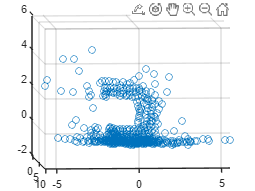

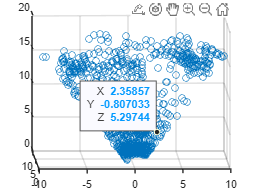

% Make a heat plot
pointsize = 10;
scatter(x, y, pointsize, z)

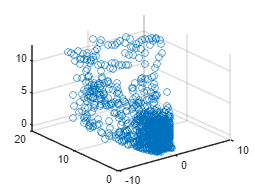

% Plot while filtering out noisy data
clf
x = x(x<15); % in / 2.54

y = y(x<15); % in / 2.54
z = z(x<15); % in / 2.54
scatter3(x,y,z);

function pos = Deg2Pos(degree)
% Maps the 180 degree range to position (0,1)
% We included negative degrees so that the mid point where we start the
% scan would be 0.
% Because the servo moves counter-clockwise, we chose to map 90 degree to position 1
% and -90 degree to position 0.
pos = 0.5-degree/180;
end

function distance = get_distance(voltage)
% Transfers voltage output to distance
distance = 18.9*exp(-0.7578*voltage);
end 


function coordinate = get_coordinates(a,pan_angle, tilt_angle)
% Convert distance measurement and bearings to spherical coordinates
    distance = get_distance(readVoltage(a,sensor_pin));
    theta = pan_angle;
    phi = tilt_angle;
    
    z = distance * sin(deg2rad(theta)) * cos(deg2rad(phi));
    y = distance * sin(deg2rad(phi));
    x = distance * cos(deg2rad(theta)) * cos(deg2rad(phi));

    coordinate = [x; y; z];
end